# Numerical Mathematics

## Polynomials

*Polynomials* $a_nx^n+\dots+a_1x+a_0$ are stored in MATLAB as the array of coefficients: `p=[a_n ... a_1 a_0]` eg., $p(x)=x^2-3x+2$

p = [1 -3 2];

The command `polyval` allows us to evaluate the polynomial in a point:

polyval(p, -2)

ans =     12


polyval(p, -1)

ans =      6


polyval(p, 0)

ans =      2


polyval(p, 1)

ans =      0


polyval(p, 2)

ans =      0


The command `roots` culculates the zeroes of a polynomial:

roots(p)

ans =      2
     1


Polynomials can be multiplicated by the operator `conv`, eg.


$$\left(x^2-1\right)\left(x^2+1\right)=x^4-1$$


conv([1 0 -1], [1, 0, 1])

ans =      1     0     0     0    -1


The command `residue` gives the partial fraction expansion of a polynomial division, eg.


$$\frac{7x-5}{x^2-x-2}=\frac{3}{x-2}+\frac{4}{x+1}$$


p1 = [7 -5];
p2 = [1 -1 -2];
[r,p,k] = residue(p1, p2)

r =      3
     4


p =      2
    -1



k =

     []




$$\frac{3x^3+2x^2+x+1}{x-1}=3x^2+5x+6+\frac{7}{x-1}$$


[r,p,k] = residue([3,2,1,1],[1,-1])

r =      7


p =      1


k =      3     5     6


*Regression* is finding the curve of best fit for a set a data points x and y. MATLAB fits a polynomial of degree $n$ using `polyfit(x, y, n)`:

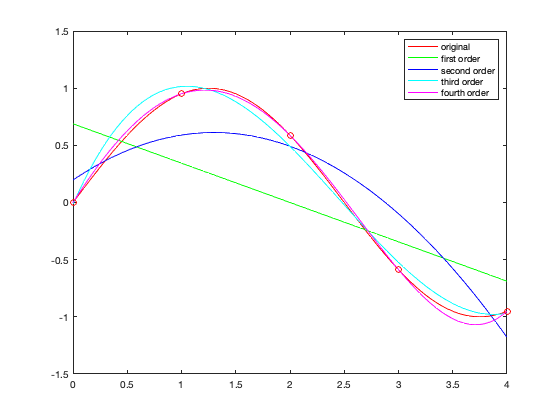

xf = 0:0.05:4;
yf = sin(2*pi*xf/5);
xp = 0:4;
yp = sin(2*pi*xp/5);
p1 = polyfit(xp, yp, 1); yp1 = polyval(p1, xf); 
p2 = polyfit(xp, yp, 2); yp2 = polyval(p2, xf);
p3 = polyfit(xp, yp, 3); yp3 = polyval(p3, xf); 
p4 = polyfit(xp, yp, 4); yp4 = polyval(p4, xf);
plot(xf,yf,'r', xf,yp1,'g', xf,yp2,'b', xf,yp3,'c', xf,yp4,'m', xp,yp,'ro')
legend('original', 'first order', 'second order', 'third order', 'fourth order')

## Vectors in 3D

A vector in $\mathbb R^3$ is represented by a column array:

v = [1;2;3];
v = transpose([1 2 3]);
v = [1 2 3]'

v =      1
     2
     3


The length of a vector in $\mathbb R^3$ is given by 


$$||\vec v|| = \sqrt{v_1^2+v_2^2+v_3^2}$$


The matlab command to calculate the length is `norm`:

norm(v)

ans = 3.7417

Do not use the command `length` that gives the number of elements in the longest dimension:

length(v)

ans = 3

The *dot product* between the vectors $\vec v$ and $\vec w$ is defined by 


$$\vec v \cdot \vec w = v_1w_1+v_2w_2+v_3w_3$$


Matlab gives the command `dot` to evaluate this product:

w = [1;1;1];
dot(v,w)

ans = 6

The *cross product* between the vectors $\vec v$ and $\vec w$ is defined by 


$$\vec v \times \vec w =\pmatrix{ \vec e_1& \vec e_2& \vec e_3\cr v_1&v_2&v_3\cr w_1&w_2&w_3} = \pmatrix{ v_2w_3-v_3w_2\cr v_3w_1-v_1w_3\cr v_1w_2-v_2w_1 }$$


u = cross(v,w)

u =     -1
     2
    -1


## Linear Algebra

Informally, the terms *matrix* and *array* are often used interchangeably. More precisely, a matrix is a two-dimensional numeric array that represents a linear transformation. The mathematical operations defined on matrices are the subject of *linear algebra*.

Dürer’s magic square

A = [16   3   2  13
      5  10  11   8
      9   6   7  12
      4  15  14   1]

A =     16     3     2    13
     5    10    11     8
     9     6     7    12
     4    15    14     1


provides several examples that give a taste of MATLAB matrix operations. You have already seen the *matrix transpose*, `A'`. Adding a matrix to its transpose produces a symmetric matrix:

  A + A'

ans =     32     8    11    17
     8    20    17    23
    11    17    14    26
    17    23    26     2


The multiplication symbol, `*`, denotes the *matrix multiplication* involving inner products between rows and columns. Multiplying the transpose of a matrix by the original matrix also produces a symmetric matrix:

  A' * A

ans =    378   212   206   360
   212   370   368   206
   206   368   370   212
   360   206   212   378


The *determinant* of this particular matrix happens to be zero, indicating that the matrix is _singular_:

  d = det(A)

d = 2.4317e-13

Since the matrix is singular, it does not have an *inverse*. If you try to compute the inverse with

  X = inv(A)

X = 	1.0e+15 *

    0.5593    1.6778   -1.6778   -0.5593
   -1.6778   -5.0334    5.0334    1.6778
    1.6778    5.0334   -5.0334   -1.6778
   -0.5593   -1.6778    1.6778    0.5593


you will get a warning message. Roundoff error has prevented the matrix inversion algorithm from detecting exact singularity. But the value of` rcond`, which stands for *reciprocal condition estimate*, is on the order of `eps`, the floating-point relative precision, so the computed inverse is unlikely to be of much use.

The *eigenvalues* of the magic square are interesting:

  e = eig(A)

e =    34.0000
    8.0000
   -0.0000
   -8.0000


One of the eigenvalues is zero, which is another consequence of singularity. The largest eigenvalue is 34, the magic sum. That is because the vector of all ones is an *eigenvector*:

v = ones(4,1);
A*v

ans =     34
    34
    34
    34


The other eigenvectors are stored as columns in the matrix `P`

[P,D] = eig(A)

P =     0.5000    0.8165    0.2236   -0.4082
    0.5000   -0.4082   -0.6708   -0.0000
    0.5000   -0.0000    0.6708   -0.4082
    0.5000   -0.4082   -0.2236    0.8165


D =    34.0000         0         0         0
         0    8.0000         0         0
         0         0   -0.0000         0
         0         0         0   -8.0000


When a magic square is scaled by its magic sum,

PR = A/34

PR =     0.4706    0.0882    0.0588    0.3824
    0.1471    0.2941    0.3235    0.2353
    0.2647    0.1765    0.2059    0.3529
    0.1176    0.4412    0.4118    0.0294


the result is a doubly *stochastic matrix* whose row and column sums are all 1.

Such matrices represent the transition probabilities in a *Markov process*. Repeated powers of the matrix represent repeated steps of the process. For our example, the fifth power is

PR^5

ans =     0.2507    0.2495    0.2494    0.2504
    0.2497    0.2501    0.2502    0.2500
    0.2500    0.2498    0.2499    0.2503
    0.2496    0.2506    0.2505    0.2493


This shows that as $k\rightarrow\infty$, all the elements in the $k$th power approaches $\frac{1}{4}$.

Finally, the coefficients in the *characteristic polynomial* are

poly(A)

ans = 	1.0e+03 *

    0.0010   -0.0340   -0.0640    2.1760    0.0000


This indicates that the characteristic polynomial $\det\left(t\mathbf{I} - \mathbf{A}\right)$ is


$$\Delta\left(t\right) = t^4-34t^3-64t^2+2176t$$


The constant term is zero, because the matrix is singular, and the coefficient of the cubic term is -34, because the matrix is magic!

## Linear Systems

A *linear system*


$$\begin{cases} a_{1,1}x_1+a_{1,2}x_2+\cdots+a_{1,n}x_n&=b_1\\ a_{2,1}x_1+a_{2,2}x_2+\cdots+a_{2,n}x_n&=b_2\\ &\vdots\\ a_{n,1}x_1+a_{n,2}x_2+\cdots+a_{n,n}x_n&=b_n\\ \end{cases}$$


can be represented as a matrix-vector equation: $\mathbf{A}\vec x=\vec b$ and its solution is $\vec x=\mathbf{A}^{-1}\vec b$.

A = [1 1  2
        2 4 -3
        3 6 -5];
b = [1; 5; 2];
x = inv(A) * b

x =   -61.0000
   40.0000
   11.0000


Another way to solve this system is based on Gaussian elimination called the *row reduced echelon form*, eg.

rref([A, b])

ans =      1     0     0   -61
     0     1     0    40
     0     0     1    11


Matlab has an operator that uses an optimized (numerical) method to solve a linear system:

x = A \ b % or linsolve(A, b)

x =   -61.0000
   40.0000
   11.0000
